# Laboratory exercises 1 for Signals and Systems 2

(Prof. Bjoern Lange, last modified November 04, 2025)

In this first lab, you will apply content of the first three lectures

- 'Introduction to discrete signals and systems',

- 'Sampling' and

- 'Discrete-time signals and LTI systems in the time domain'.

Comments:

- You will need to install both 'Control System Toolbox' and 'Signal Processing Toolbox'. 

- Prepare by carefully reading the instructions given below. If necessary, review the corresponding content in the lecture notes. Read the MATLAB documentation for the proposed built-in functions.

- Since the first laboratory session is a short one, the solutions are already included. Stay curious and feel free to modify and try out different signals, systems, parameter combinations and function options! 

### Exercise 1: Reconstruction of a signal from sampled data

Consider the signal


$$x(t)=4\sin(2\pi t)+\cos (\frac{\pi}{4}+16\pi t).$$


a) Quasi-continuously plot $x(t)$ in the time range $[0,1]$ by choosing a very small time step for plotting, e.g. $dT=0.0025$.

Remark: If not using symbolic math, MATLAB can not deal with a time axis that is truly continuous (computer memory is limited). But signals *appear* to be continuous-time if the time step used for plotting is smaller than the screen's graphical resolution.

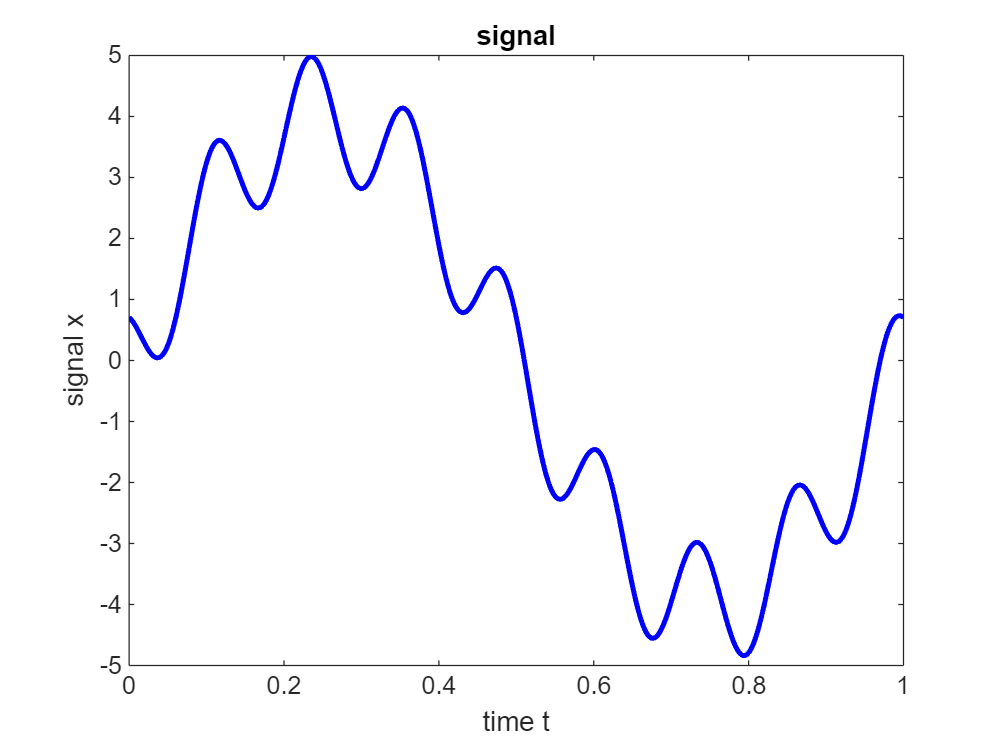

dT = 0.0025;                            % small time step for the quasi continuous-time signal
t = 0:dT:1;                             % time vector
x = 4*sin(2*pi*t)+cos(pi/4+16*pi*t);    % signal vector
                            
figure()  
plot(t,x,'b','Linewidth',2);                               
title('signal'); xlabel('time t'); ylabel('signal x');

b) Using the MATLAB function `downsample()` from the Signal Processing Toolbox, sample the signal $x(t)$ at instants $n\cdot T_s$*, *with $T_s=m\cdot dT$ being a multiple of the small time step $dT$ used above for the quasi continuous-time plotting of $x(t)$. A higher value of $m$ (taken from the set of natural numbers) corresponds to a larger sampling period $T_s$ and, correspondingly, a smaller sampling frequency $f_s=1/T_s$*. *Display the sampled sequence $x[n], n \in \mathbb{Z}$ together with the quasi continuous-time signal $x(t)$.  

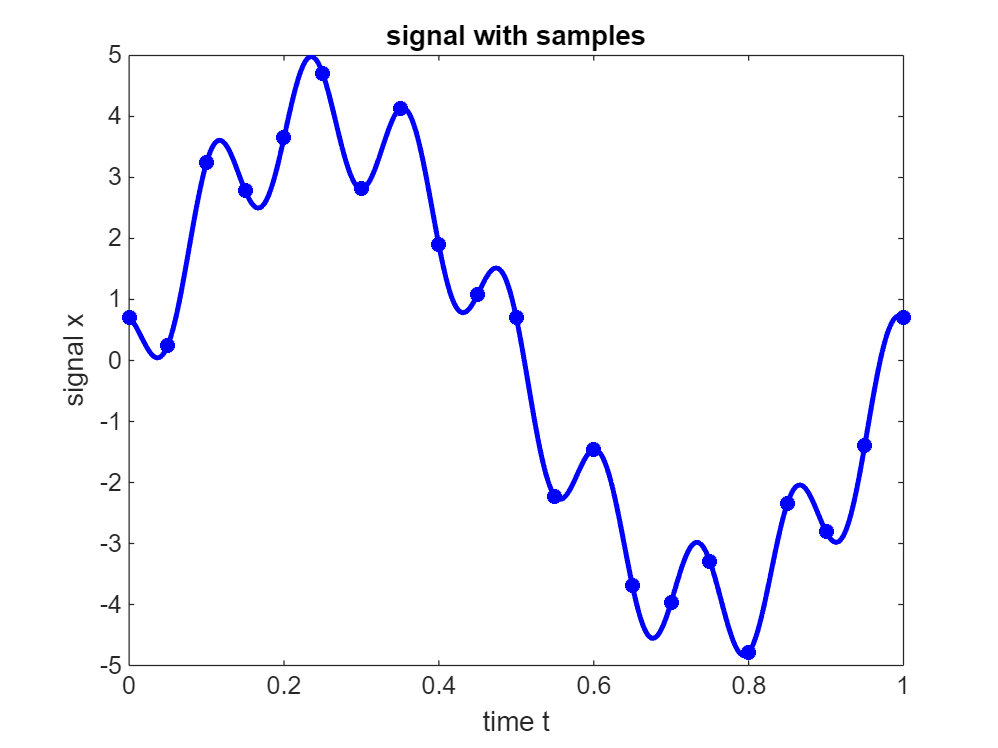

m = 20;                             % every m-th value will be sampled
T_s = m*dT;                         % sampling period 
t_n = downsample(t,m);              % time vector for the samples
x_n = downsample(x,m);              % downsampled signal
figure()
plot(t,x,'b',t_n,x_n,'b*','Linewidth',2);          
title('signal with samples'); xlabel('time t'); ylabel('signal x');

c) Try several values for $m$. You might be able to guess from the sampled values whether the Nyquist criterion $f_s>2\,f_c$ is met or not. Considering the cut-off frequency $f_c$ of the given signal $x(t)$ and the value chosen for $dT$ in subtask a), what is the maximum value for $m$ that still allows full recovery of the original signal from the samples?

d) If the Nyquist criterion is met, the signal *x(t)* can be reconstructed from the sequence of samples $x[n]$ by employing the formula 


$$x(t)=\sum_{k=-\infty}^{\infty}x[k]\cdot\mbox{sinc}\big(\frac{\pi\cdot (t-kT_s)}{T_s}\big).
$$


Review the definition of the `sinc()` function in the MATLAB documentation (which is different from the definition given in the lecture). Reconstruct the signal $x(t)$ and plot it in a new window. It is interesting to also display the sampled values, the individual summands and, as a check, the original signal $x(t)$. Why do you not see the red line that is plotted for the reconstructed signal in the figure?

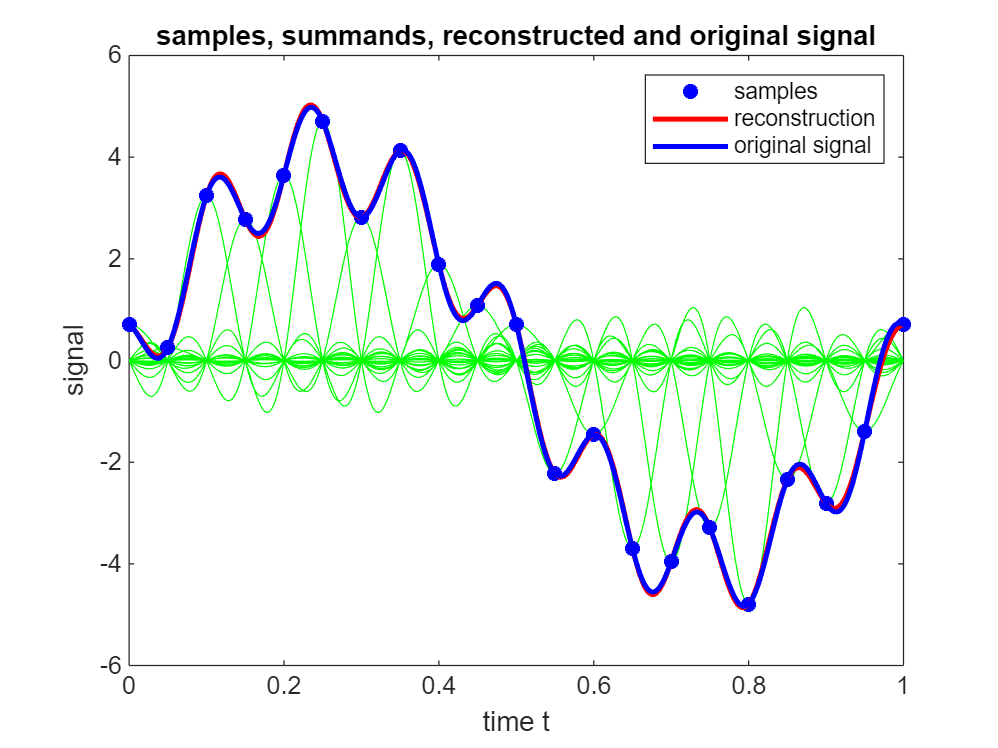

figure(); hold on; box on; 
x_sum = 0*t;                                % initialize summand vector
for k = 1:length(x_n)                       % looping over all samples, note: x(k=1) represents sample x[0] from the lecture
                                            % (indices must be positive integers in MATLAB)
    s = x_n(k)*sinc((t-(k-1)*T_s)/T_s);     % summand for sample x_n(k)
    plot(t,s,'g','HandleVisibility','off'); % plot individual summands, suppressing legend entry
    x_sum = x_sum+s;                        % summing of summands
end
plot(t_n,x_n,'b*',t,x_sum,'r',t,x,'b','Linewidth',2);
title('samples, summands, reconstructed and original signal');
legend('samples','reconstruction','original signal')
xlabel('time t'); ylabel('signal');
hold off;

e) Try values of $m$ that violate the Nyquist criterion and observe what happens.

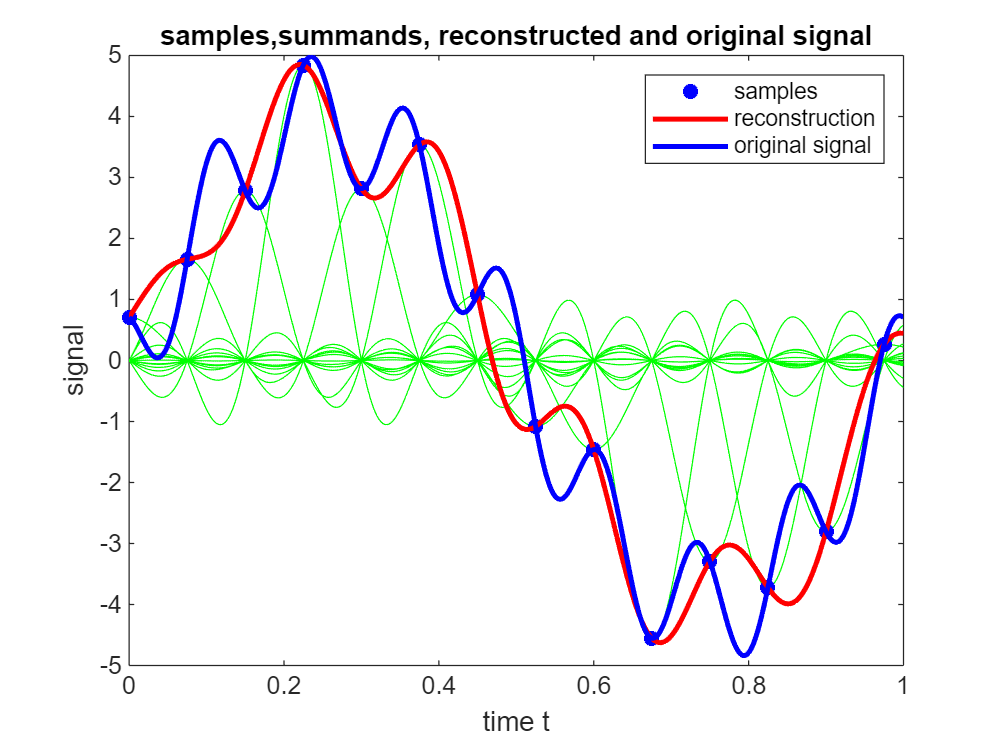

m = 30;                % every m-th value will be sampled
T_s = m*dT;            % sampling period
t_n = downsample(t,m); % time vector for the samples
x_n = downsample(x,m); % downsampled signal

figure(); hold on; box on;

x_sum = 0*t;                                % initialize summand vector
for k = 1:length(x_n)                       % looping over all samples
    s = x_n(k)*sinc((t-(k-1)*T_s)/T_s);     % summand for sample x_n(k)
    plot(t,s,'g','HandleVisibility','off'); % plot individual summands, suppressing legend entry
    x_sum = x_sum+s;                        % summing of summands
end
plot(t_n,x_n,'b*',t,x_sum,'r',t,x,'b','Linewidth',2);
title('samples,summands, reconstructed and original signal');
legend('samples','reconstruction','original signal')
xlabel('time t'); ylabel('signal');
hold off;

### Exercise 2: Discretization of LTI-systems in the time domain

Consider the two following two systems that are well-known from the lectures. 

System 1:

 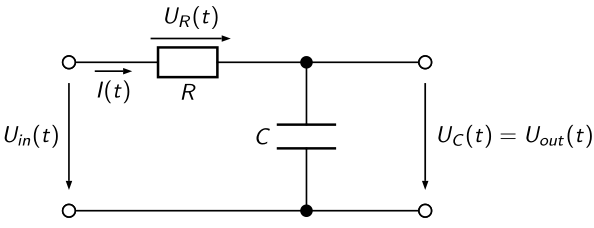         

With $x(t)=U_{in}(t), y(t)=U_{out}(t)$ and $\tau=RC$, system 1 is described by the differential equation $\tau\,\dot{y}(t)+y(t)=x(t)$.

System 2:

       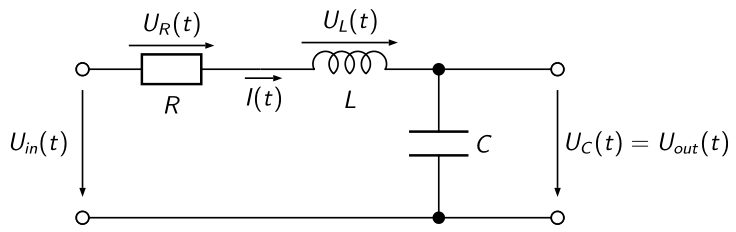

With $x(t)=U_{in}(t), y(t)=U_{out}(t), \tau=RC$ and $\omega_r=\frac{1}{\sqrt{LC}}$, system 2 is described by the differential equation $\frac{1}{\omega_r^2}\cdot \ddot{y}(t)+\tau\cdot \dot{y}(t)+y(t)=x(t)$.

In the lecture we discretized these differential equations and then had to invest some work in solving the resulting difference equations. We can now let MATLAB do the job and compare the impulse and step responses for both the continuous-time systems and their discrete-time counterparts.

a) Determine the continuous-time matrix form state space representations 


$$\dot{\textbf{x}}(t)=\textbf{A}\cdot\textbf{x}(t)+\textbf{b}\cdot x(t)\\
y(t)=\textbf{c}^T\cdot\textbf{x}(t)+d \cdot x(t)$$


for the two systems. Review last semester's SS1 lecture 5 and laboratory session 2 if necessary.

b) Define constants for the components. Reasonable values to start with are $R = 10\,\Omega, C = 10\,\text{mF}$ and $L = 100\,{\text{mH}.$

% definition of the system parameters
R  = 10;          % resistance
C  = 0.01;        % capacitance
L  = 0.100;       % inductance
tau = R*C;        % constant 1
wr = 1/sqrt(L*C); % constant 2

c) Declare `sys1 `and `sys2` as representatives for system 1 and 2 in MATLAB. This can easily be done with the built-in function `sys()`, e.g. `sys1=ss(A,b,c,d)`. For a SISO-system, the arguments of `ss()` are $\mathbf{A}, \mathbf{b}, \mathbf{c}$ and $d$ from the matrix representation that you determined in subtask a).

% declaration of the continuous-time systems
A1   = -1/tau;
b1   = 1;
c1   = 1/tau;
d1   = 0;
sys1 = ss(A1,b1,c1,d1); % RC low-pass filter

A2   = [0 -wr^2; 1 -tau*wr^2];
b2   = [1; 0];
c2   = [0 wr^2];
d2   = 0;
sys2 = ss(A2,b2,c2,d2); % RLC resonant circuit

d) Use the MATLAB functions `impulse()` und `step()` to display the impulse responses of both systems in an upper subplot and the step responses of both systems in a lower subplot. Both functions can handle multiple systems in one call.

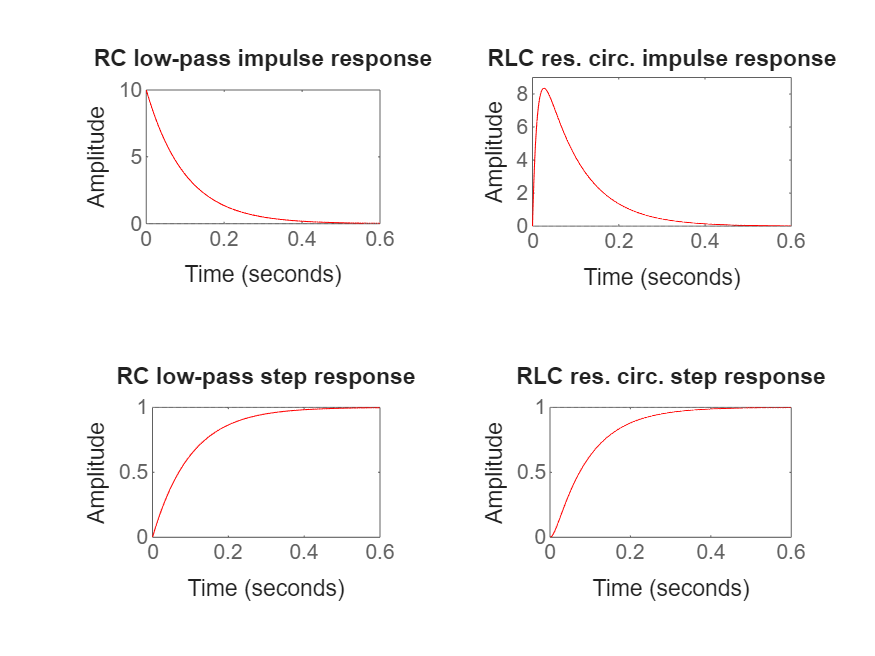

% impulse and step responses of both systems
figure();
subplot(221);      % upper left plot in a 2x2 plot matrix
impulse(sys1,'r'); % determine and plot impulse response
title('RC low-pass impulse response')
subplot(222);      % upper right plot in a 2x2 plot matrix
impulse(sys2,'r'); % determine and plot impulse response
title('RLC res. circ. impulse response')
subplot(223);      % lower left plot in a 2x2 plot matrix
step(sys1,'r');    % determine and plot step response
title('RC low-pass step response')
subplot(224);      % lower right plot in a 2x2 plot matrix
step(sys2,'r');    % determine and plot step response
title('RLC res. circ. step response')

e)  With the discretization method for differential equations introduced in the lecture, we found the following difference equations for both systems:

System 1: $y[n]-\frac{\tau}{\tau+T_s}\cdot y[n-1]=\frac{T_s}{\tau+T_s}\cdot x[n]$

System 2: $y[n]-\frac{2+\tau\,T_s\,\omega_r^2}{1+\tau\,T_s\,\omega_r^2+(T_s\,\omega_r)^2}\cdot y[n-1]+\frac{1}{1+\tau\,T_s\,\omega_r^2+(T_s\,\omega_r)^2}\cdot y[n-2]=\frac{(T_s\,\omega_r)^2}{1+\tau\,T_s\,\omega_r^2+(T_s\,\omega_r)^2}\cdot x[n]$

Determine the discrete-time matrix form state space representations 


$$\textbf{x}[n]=\textbf{A}\cdot\textbf{x}[n-1]+\textbf{b}\cdot x[n-1]\\
y[n]=\textbf{c}^T\cdot\textbf{x}[n]+d\cdot x[n].$$


for the two systems using the method shown in this semester's SS2 lecture 3 (note that $\mathbf{x}[n]$ is the vector of state variables at index $n$, while $x[n]$ is the $n^\text{th}$ sample of the input signal).

f) Declare the discrete-time state space representations `sys1_d` and `sys2_d` of the given systems. In MATLAB, this is also done with the `sys()` function, e.g. `sys1=ss(A,b,c,d,T_s)`. The first four arguments of ss() are $\mathbf{A}, \mathbf{b}, \mathbf{c}$ and $d$ from the discrete matrix representation that you determined in subtask e). The fifth argument (mandatory for discrete-time systems) is the sampling period $T_s.$

% declaration of the discrete-time systems
T_s    = 0.01;
a_1    = -tau/(tau+T_s);
b_0    = T_s/(tau+T_s);
A1     = -a_1;
b1     = -a_1*b_0;
c1     = 1;
d1     = b_0;
sys1_d = ss(A1,b1,c1,d1,T_s);

a_1    = -(2+tau*T_s*wr^2)/(1+tau*T_s*wr^2+(T_s*wr)^2);
a_2    = 1/(1+tau*T_s*wr^2+(T_s*wr)^2);
b_0    = (T_s*wr)^2/(1+tau*T_s*wr^2+(T_s*wr)^2);
b_1    = 0;
A2     = [0 -a_2; 1 -a_1];
b2     = [-a_2*b_0; b_1-a_1*b_0];
c2     = [0 1];
d2     = b_0;
sys2_d = ss(A2,b2,c2,d2,T_s);

g) Compare continuous-time and discrete-time solutions in a two subplots similar to those of subtask d). Vary the sampling time $T_s$ and observe the differences between continuous and discrete systems for both impulse and step responses. 

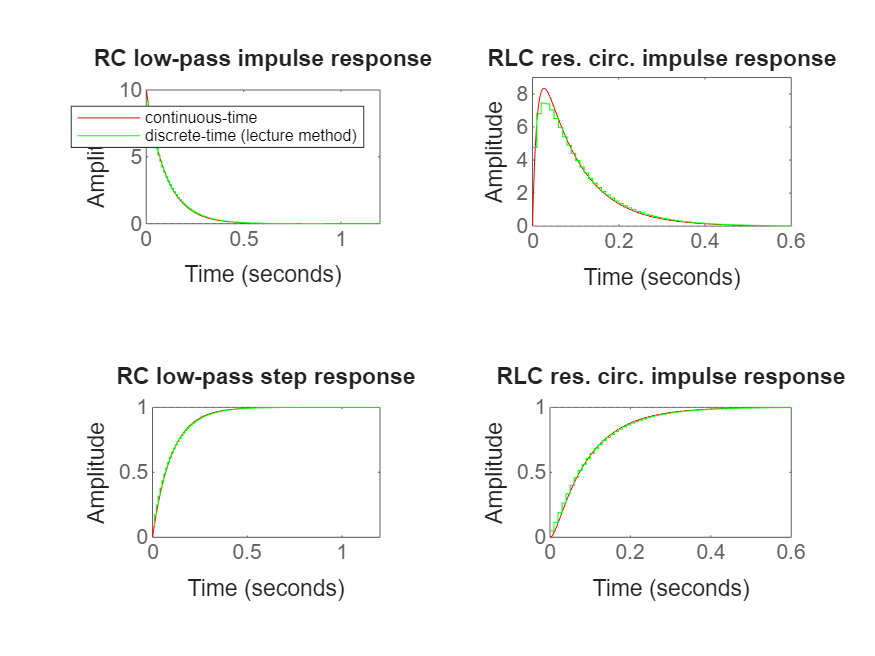

% plotting impulse and step responses for both continuous-time and discrete-time for comparison
figure()
subplot(221)
impulse(sys1,'r',sys1_d,'g');
legend('continuous-time','discrete-time (lecture method)')
title('RC low-pass impulse response')
subplot(222)
impulse(sys2,'r',sys2_d,'g');
title('RLC res. circ. impulse response')
subplot(223)
step(sys1,'r',sys1_d,'g');
title('RC low-pass step response')
subplot(224)
step(sys2,'r',sys2_d,'g');
title('RLC res. circ. impulse response')

h) MATLAB can also automatically discretize systems. This is done by the `c2d()` function that converts a continuous-time system into a discrete-time system. Various discretization options are described in the function documentation. Compare our hand-made discretization from the lecture with the options offered by MATLAB (feel free to choose the default option).

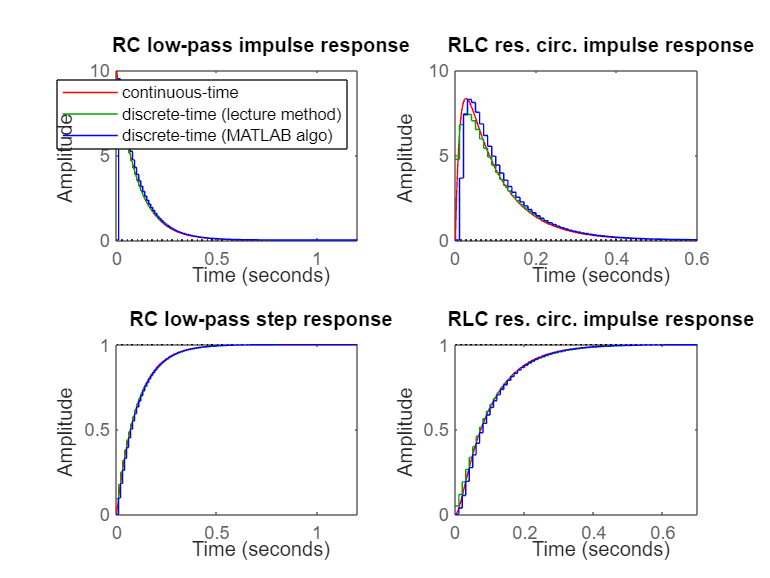

% let MATLAB discretize the systems
sys1_d2 = c2d(sys1,T_s);
sys2_d2 = c2d(sys2,T_s);
% plotting impulse and step responses
figure()
subplot(221)
impulse(sys1,'r',sys1_d,'g',sys1_d2,'b');
legend('continuous-time','discrete-time (lecture method)','discrete-time (MATLAB algo)')
title('RC low-pass impulse response')
subplot(222)
impulse(sys2,'r',sys2_d,'g',sys2_d2,'b');
title('RLC res. circ. impulse response')
subplot(223)
step(sys1,'r',sys1_d,'g',sys1_d2,'b');
title('RC low-pass step response')
subplot(224)
step(sys2,'r',sys2_d,'g',sys2_d2,'b');
title('RLC res. circ. impulse response')

i) With the parameter combination specified above, the step response of the second order system is monotonously growing. Try other combinations of the values $R, C$ and $L$ to observe oscillation in the impulse and step response of system 2. Compare the quality of the discretization from the lecture with the automatic discretization offered by MATLAB.

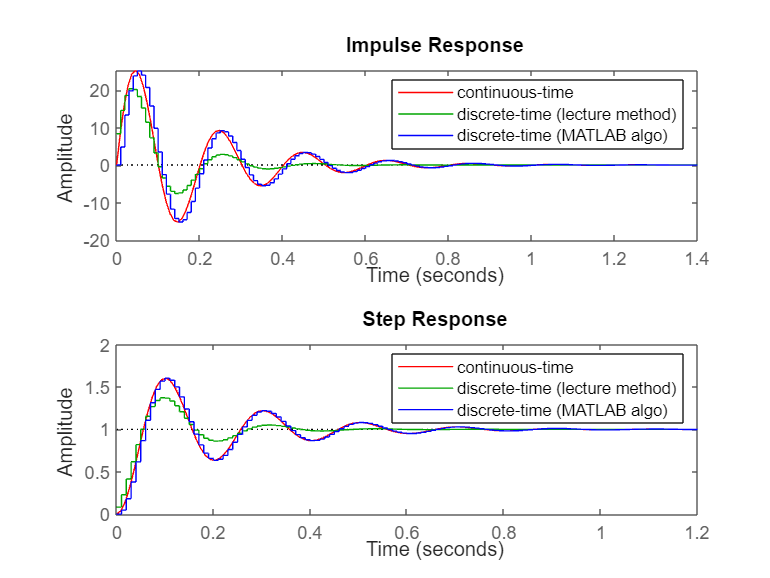

% definition of the system parameters
R  = 1;           % resistance
C  = 0.01;        % capacitance
L  = 0.100;       % inductance
tau = R*C;        % constant 1
wr = 1/sqrt(L*C); % constant 2

% declaration of the continuous-time system
A2    = [0 -wr^2; 1 -tau*wr^2];
b2    = [1; 0];
c2    = [0 wr^2];
d2    = 0;
sys2  = ss(A2,b2,c2,d2);

% declaration of the discrete-time system
a_1    = -(2+tau*T_s*wr^2)/(1+tau*T_s*wr^2+(T_s*wr)^2);
a_2    = 1/(1+tau*T_s*wr^2+(T_s*wr)^2);
b_0    = (T_s*wr)^2/(1+tau*T_s*wr^2+(T_s*wr)^2);
b_1    = 0;
A2     = [0 -a_2; 1 -a_1];
b2     = [-a_2*b_0; b_1-a_1*b_0];
c2     = [0 1];
d2     = b_0;
sys2_d = ss(A2,b2,c2,d2,T_s);

% let MATLAB discretize the system
sys2_d2 = c2d(sys2,T_s);

% plotting impulse and step responses
figure()
subplot(211)
impulse(sys2,'r',sys2_d,'g',sys2_d2,'b');
legend('continuous-time','discrete-time (lecture method)','discrete-time (MATLAB algo)')
subplot(212)
step(sys2,'r',sys2_d,'g',sys2_d2,'b');
legend('continuous-time','discrete-time (lecture method)','discrete-time (MATLAB algo)')